%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all
clc
close all


filename = '/home/saliyar/OpenFOAM/MoorDynV2/MoorDyn/Mooring/Lines.out';
            fid = fopen(filename, 'r');
            header = strsplit(fgetl(fid));
            data = dlmread(filename,'',3,0);
            tmp = size(data);
            ncol = tmp(2);clear tmp
            for icol=1:ncol
               eval(['obj.moorDyn.Lines.' header{icol} ' = data(:,' num2str(icol) ');']);
            end
fclose(fid);


## Plotting the Fairlead tension at SPAR junction

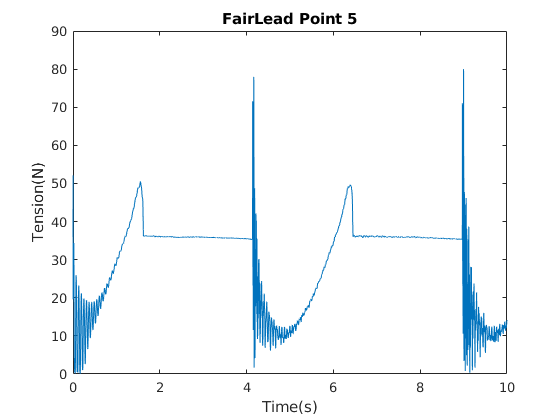

figure()
plot(data(:,1),data(:,5))
title('FairLead Point 5')
xlabel('Time(s)')
ylabel('Tension(N)')

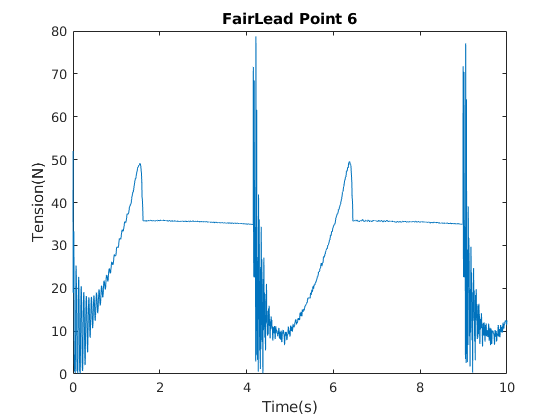


figure()
plot(data(:,1),data(:,6))
title('FairLead Point 6')
xlabel('Time(s)')
ylabel('Tension(N)')

## Plotting Fairlead tension at connection point

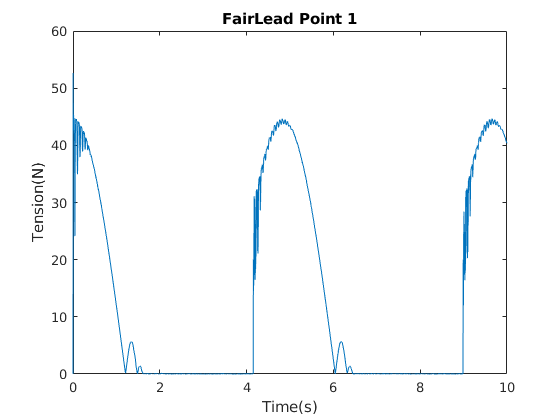

figure()
plot(data(:,1),data(:,2))
title('FairLead Point 1')
xlabel('Time(s)')
ylabel('Tension(N)')